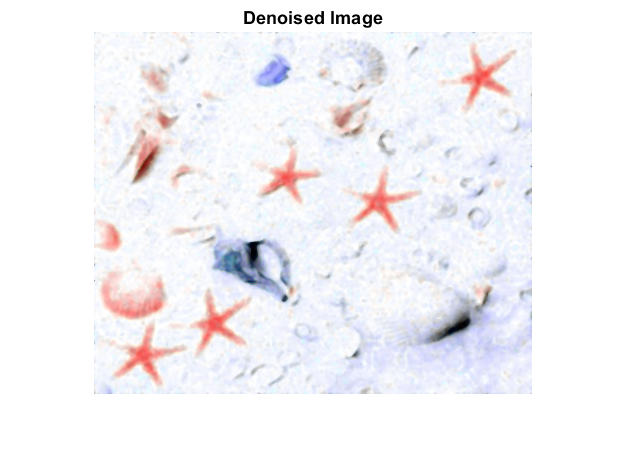

Starfish = imread('starfish.jpg');
Starfish2 = imread('starfish_noise9.jpg');
Starfish3 = imread('starfish_map1.jpg');
Starfish4 = imread('starfish_5.jpg'); 

% Denoise using median filter
StarfishDenoise = medfilt3(Starfish3);
GreyStarfish = rgb2gray(StarfishDenoise);
imshow(StarfishDenoise)
title("Denoised Image");

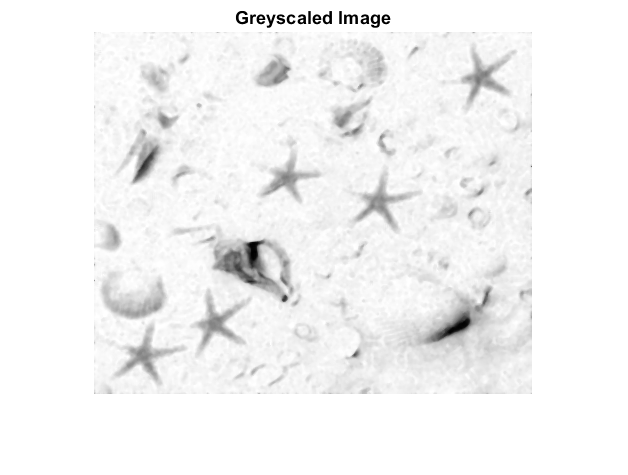

imshow(GreyStarfish);
title("Greyscaled Image")

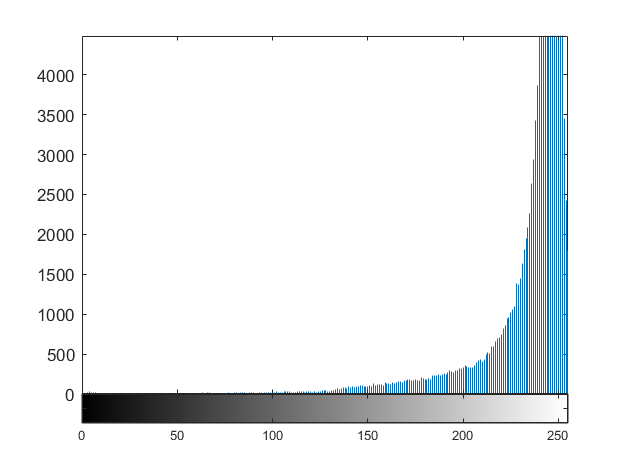

Noise = estimate_noise(GreyStarfish);
if(Noise > 3.5)
    GreyStarfish = medfilt2(GreyStarfish);
    imshow(GreyStarfish);
    title("Greyscale Denoised Image")
end
%GreyStarfish = medfilt2(GreyStarfish);


imhist(GreyStarfish);

% Get properties of gray-level co-occurrence matrix
GlcmX = graycomatrix(GreyStarfish,'Offset',[1 1])

GlcmX =          186          37          18           6           0           0           0           0
          47          58          54          33           4           0           0           0
           7          80         185         101          31           0           2           0
           3          17         108         432         227          28           3           0
           2           3          34         213        1785         672          42           1
           1           0           3          25         639        3838        1297          48
           1           1           4           9          57        1278       10373        3085
           0           0           0           0           8          55        3202      129414


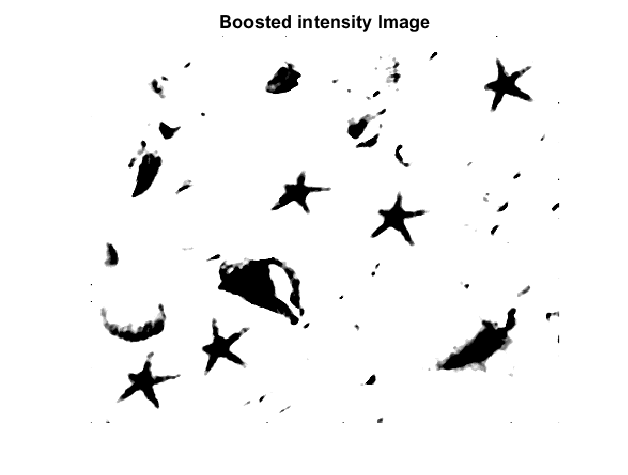

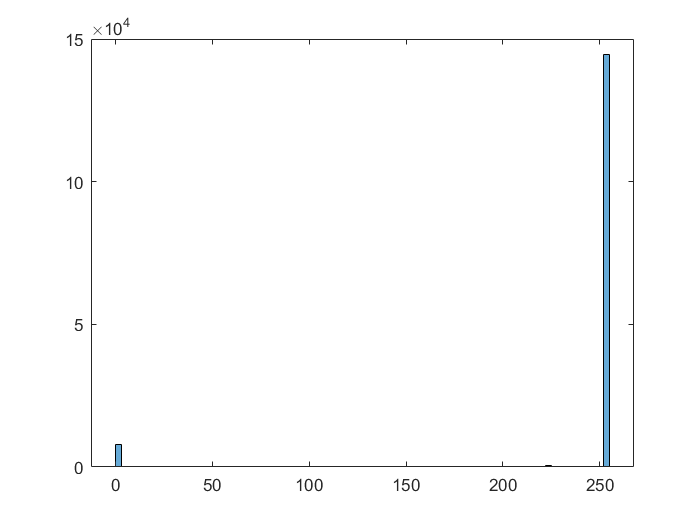

Stat = graycoprops(GlcmX);

% Boost Green Contrast of the greyscale if the Contrast of
% the greyscaled image is too low
if Stat.Contrast < 0.09
    %         Adjust contrast using specify limits
    if Stat.Contrast > 0.08 && Stat.Energy < 0.68
        GreyStarfish = imadjust(GreyStarfish,[0.71  0.8]);
    else
        GreyStarfish = imadjust(StarfishDenoise(:,:,2));
    end
     imshow(GreyStarfish);
     title("Boosted intensity Image");
     figure;
     histogram(GreyStarfish);
end

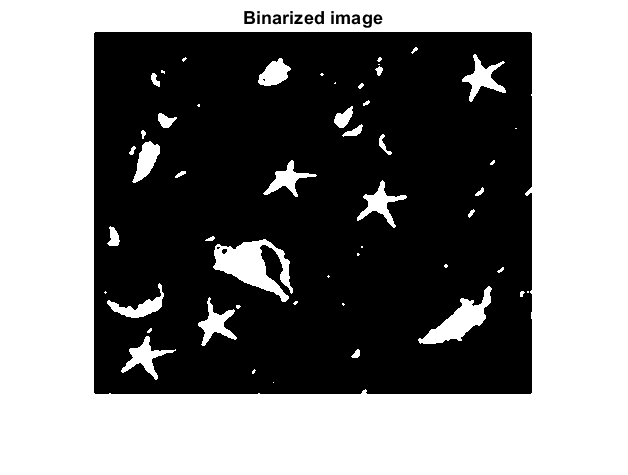


% Threshold and binarize the image
thresholdStarfish = graythresh(GreyStarfish);
GreyStarfish = medfilt2(GreyStarfish);
BW1 = imbinarize(GreyStarfish,thresholdStarfish);
BW1 = imcomplement(BW1);
imshow(BW1);
title("Binarized image")

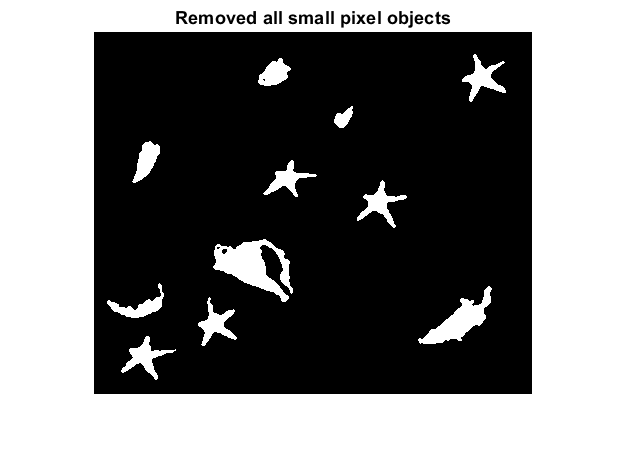


% Get rid of all small pixel objects
BW2 = bwareaopen(BW1, 200);
imshow(BW2)
title("Removed all small pixel objects")

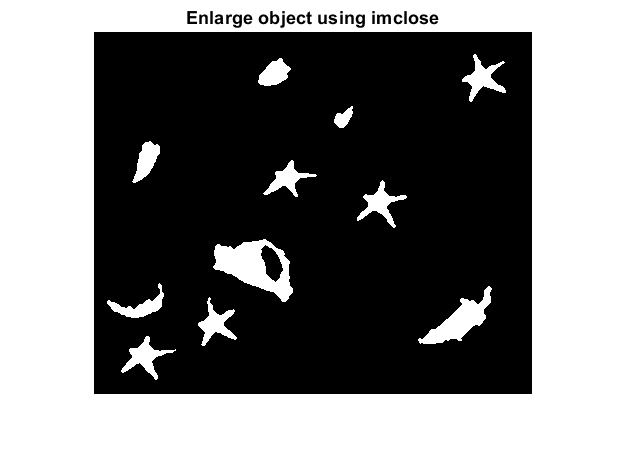


% Enlarge objects
se = strel('diamond',4); 
BW2 = imclose(BW2,se);
imshow(BW2)
title("Enlarge object using imclose");


% Get measure properties of image regions
cc = bwconncomp(BW2)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [362 438]
      NumObjects: 11
    PixelIdxList: {[639×1 double]  [756×1 double]  [610×1 double]  [721×1 double]  [2505×1 double]  [576×1 double]  [650×1 double]  [237×1 double]  [741×1 double]  [1553×1 double]  [775×1 double]}


info = regionprops(cc,'all');

% Remove any object with hole
labeledImage = bwlabel(BW2);
Hole = [info.EulerNumber]

Hole =      1     1     1     1     0     1     1     1     1     1     1


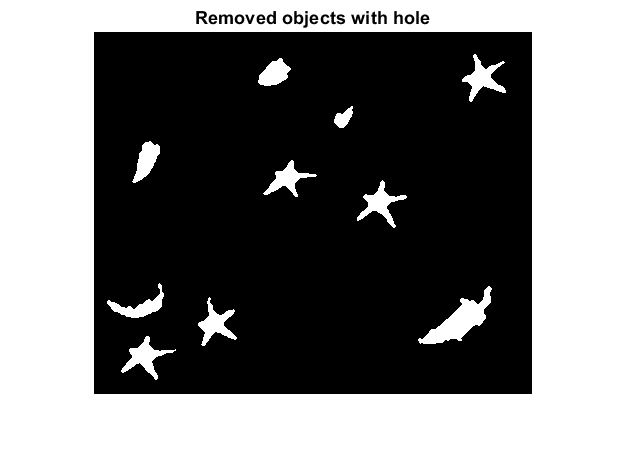

Keep = find(Hole == 1);
BW3 = ismember(labeledImage,Keep) > 0;
imshow(BW3);
title("Removed objects with hole");

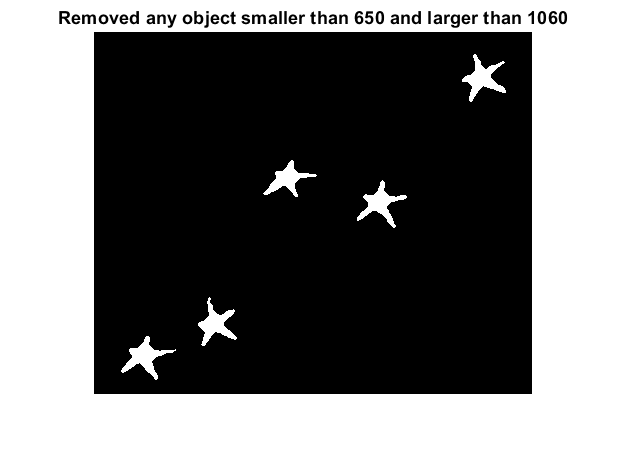


% Remove any object smaller than 650 and larger than 1060
BW3 = xor(bwareaopen(BW3, 650), bwareaopen(BW3,1060));
imshow(BW3);
title("Removed any object smaller than 650 and larger than 1060");

cc = bwconncomp(BW3)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [362 438]
      NumObjects: 5
    PixelIdxList: {[756×1 double]  [721×1 double]  [650×1 double]  [741×1 double]  [775×1 double]}


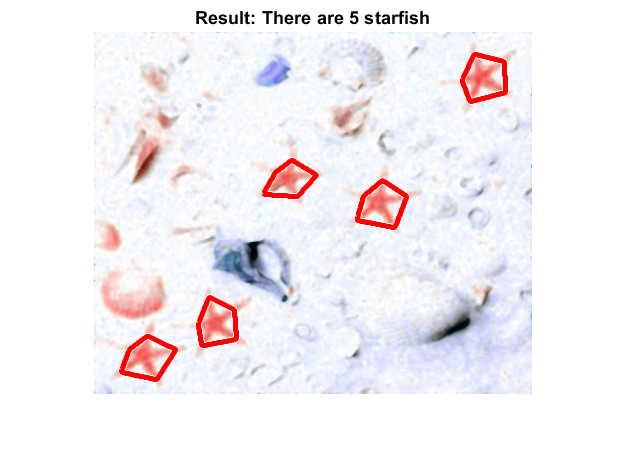

info2 = regionprops(cc,'all');
bw = edge(BW3,'sobel');

% Mark out the end result
figure;
imshow(StarfishDenoise);
Count =string(length(info2));
hold on
CH = bwconvhull(BW3,'objects');
visboundaries(CH,'Color','r',"LineWidth",3);
Str = append("Result: There are ", Count, " starfish");
title(Str);
hold off



% info = regionprops(CH,'BoundingBox') ;
% hold on
% for k = 1 : length(info)
%      BB = info(k).BoundingBox;
%      rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','g','LineWidth',3) ;
% end


function Sigma=estimate_noise(I)
[H W]=size(I);
I=double(I);
M=[1 -2 1; -2 4 -2; 1 -2 1];
Sigma=sum(sum(abs(conv2(I, M))));
Sigma=Sigma*sqrt(0.5*pi)./(6*(W-2)*(H-2));
end